close all, clear all, clc, format compact

data = xlsread('C:\Users\tcttn\Desktop\matlab\veri.xlsx')

data =         1000         975           0
         100         990           1
         980         110           1
          95         170           0


input = data(:,1:2)

input =         1000         975
         100         990
         980         110
          95         170


target = data(:,end)

target =      0
     1
     1
     0



% number of samples of each class
K = 1;
% define 4 clusters of input data
q = .6; % offset of classes
A = input(1,:)

A =         1000         975


B = input(2,:)

B =    100   990


C = input(3,:)

C =    980   110


D = input(4,:)

D =     95   170


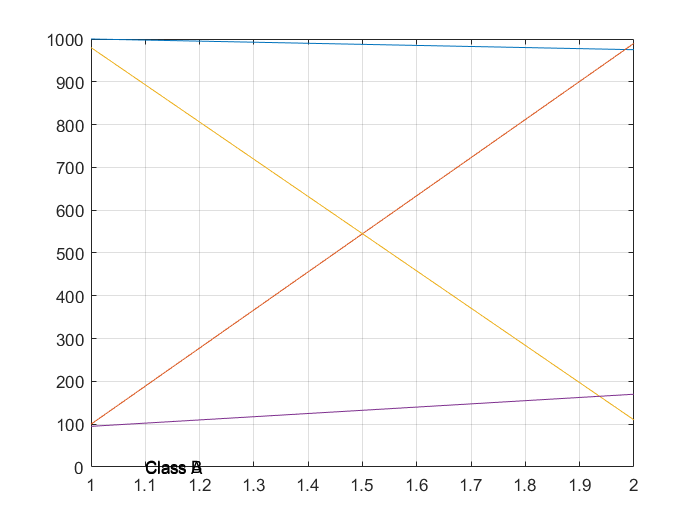

% plot clusters
figure(1)
plot(A(1,:))
hold on
grid on
plot(B(1,:))
plot(C(1,:))
plot(D(1,:))
% text labels for clusters
text(.5-q,.5+2*q,'Class A')
text(.5+q,.5+2*q,'Class B')
text(.5+q,.5-2*q,'Class A')
text(.5-q,.5-2*q,'Class B')

% encode clusters a and c as one class, and b and d as another class
a = -1; % a | b
c = -1; % -------
b = 1; % d | c
d = 1; %

% define inputs (combine samples from all four classes)
P = [A B C D];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B)) ...
 repmat(c,1,length(C)) repmat(d,1,length(D)) ];
% view inputs |outputs
%[P' T']

% create a neural network
net = feedforwardnet([5 3]);
% train net
net.divideParam.trainRatio = 1; % training set [%]
net.divideParam.valRatio = 0; % validation set [%]
net.divideParam.testRatio = 0; % test set [%]
% train a neural network
[net,tr,Y,E] = train(net,P,T);

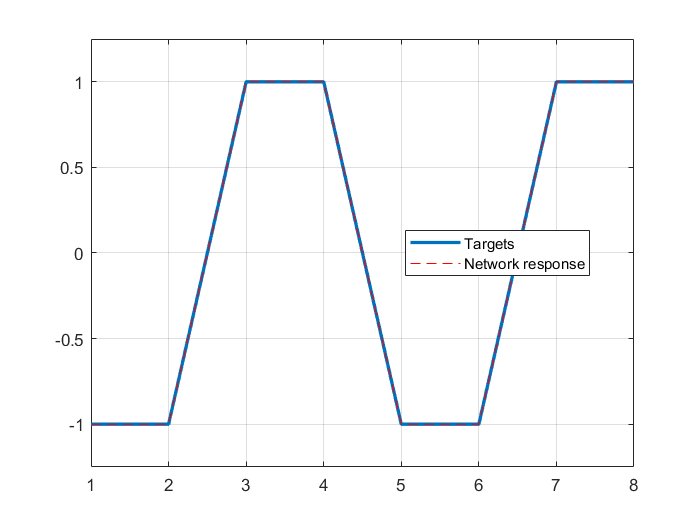

% show network
view(net)
figure(2)
plot(T','linewidth',2)
hold on
plot(Y','r--')
grid on
legend('Targets','Network response','location','best')
ylim([-1.25 1.25])

% generate a grid
span = -1:.005:2;
[P1,P2] = meshgrid(span,span);
pp = [P1(:) P2(:)]';
% simulate neural network on a grid
aa = net(pp);

Error using network/sim (line 270)
Input data sizes do not match net.inputs{1}.size.
Error in network/subsref (line 15)
        otherwise, v = sim(vin,subs{:});

% translate output into [-1,1]
%aa = -1 + 2*(aa>0);
% plot classification regions
figure(1)
mesh(P1,P2,reshape(aa,length(span),length(span))-5);
colormap cool
